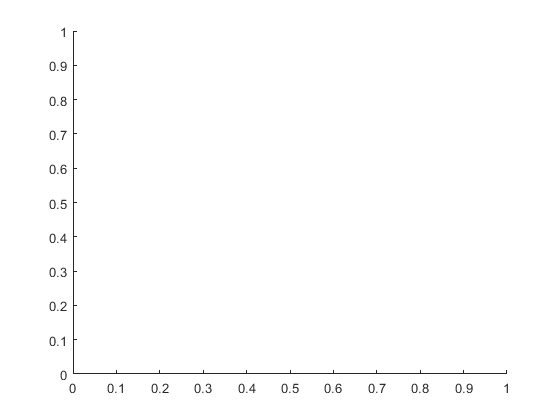

clc
clear

cycles = 300;
automat = automata(18,18,1000);

stats = [0 0 0 0 0 0];

fprintf("START SIM\n")

START SIM



tic()
time_start = toc();
lastsize = 0;
for i=1:cycles
    %% TIMING START
    pause(0.0000001)
    time_f_start = toc();
    
    %% SIMULATION CODE
    
    automat = automat.update(); % updating automata to next time cycle
    stats(i,:) = automat.get_stats(); % getting current cell state statistics
    
    % EXAMPLE USE OF ENFORCING RULES
    % making cells start to wear masks if >30% start population is infected
    % and revoking if less than 0.05 are infected
    % REMEMBER TO USE automat.enforced_masks or .enforced_lockdown flags
    % otherwise simulation will be slow AF
    if ((automat.enforced_masks == 0) && (stats(i,3) > automat.startpop * 0.3))
        automat = automat.enforce_masks();
    elseif ((automat.enforced_masks == 1) && (stats(i,3) < automat.startpop * 0.05))
        automat = automat.revoke_masks();
    end
    % same deal here global lockdown
%     automat = automat.enforce_lockdown();
    
    
    %% TIMING END  
    time_f_end = toc();
    time_elapsed = time_f_end - time_start;
    time_elapsed_f = time_f_end - time_f_start;
    eta = time_elapsed_f * (300-i);

%     fprintf(repmat('\b', 1, lastsize));
%     lastsize = fprintf("Update cycle %i, Elapsed: %f, F time: %f, ETA: %f\n",i,time_elapsed,time_elapsed_f,eta);
    lastsize = printStatus(i,lastsize,time_elapsed,time_elapsed_f,eta);
%     fprintf("\bUpdate cycle %i, Elapsed: %f, F time: %f, ETA: %f \n",i,time_elapsed,time_elapsed_f,eta)
end

Update cycle 300, Elapsed: 8.073346, F time: 0.023219, ETA: 0.000000


fprintf("END SIM\n")

END SIM


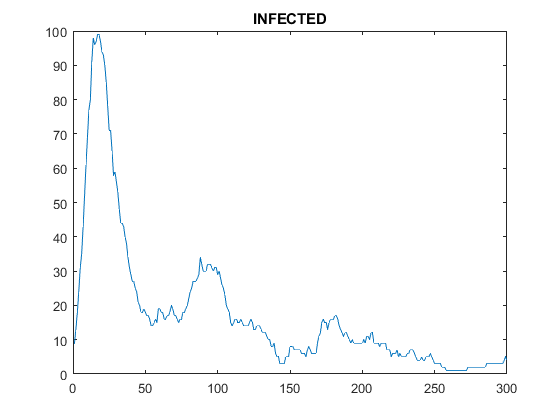


figure()
plot(stats(:,1),stats(:,3));
title("INFECTED")

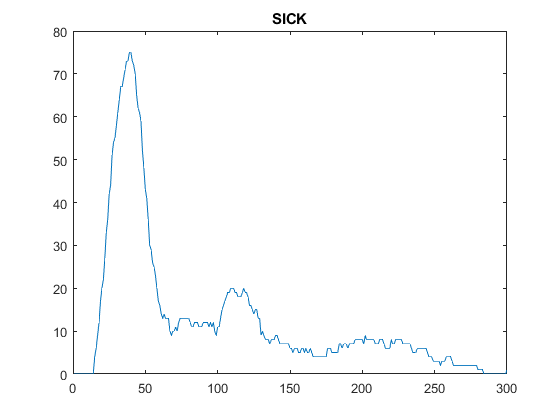


figure()
plot(stats(:,1),stats(:,4));
title("SICK")

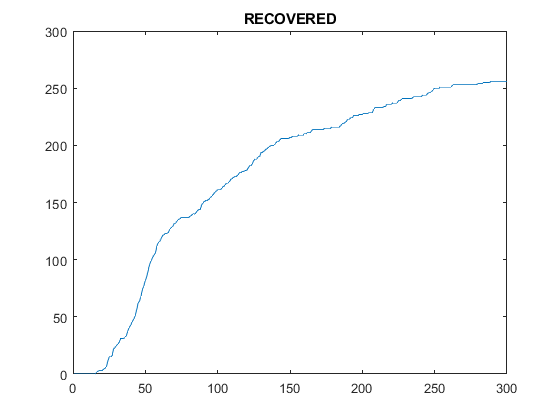


figure()
plot(stats(:,1),stats(:,5));
title("RECOVERED")

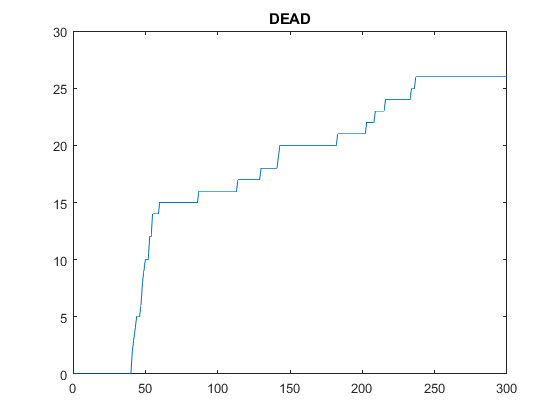


figure()
plot(stats(:,1),stats(:,6));
title("DEAD")

function lastsize = printStatus(i,lastsize,time_elapsed,time_elapsed_f,eta)
    fprintf(repmat('\b', 1, lastsize));
    lastsize = fprintf("Update cycle %i, Elapsed: %f, F time: %f, ETA: %f\n",i,time_elapsed,time_elapsed_f,eta);
end